%define variables
syms a b c
%define data
x=[1,2,3,4];
y=[7,6,4,1];
%define your function
f=0;
for i=1:length(x)
f=f+((a*x(i).^2+b*x(i)+c)-y(i))^2;
end
%calculate derivatives
da=diff(f,a);
db=diff(f,b);
dc=diff(f,c);
%solve the equations
sol=solve([da==0,db==0,dc==0],[a,b,c]);
disp(sol);

    a: -1/2
    b: 1/2
    c: 7



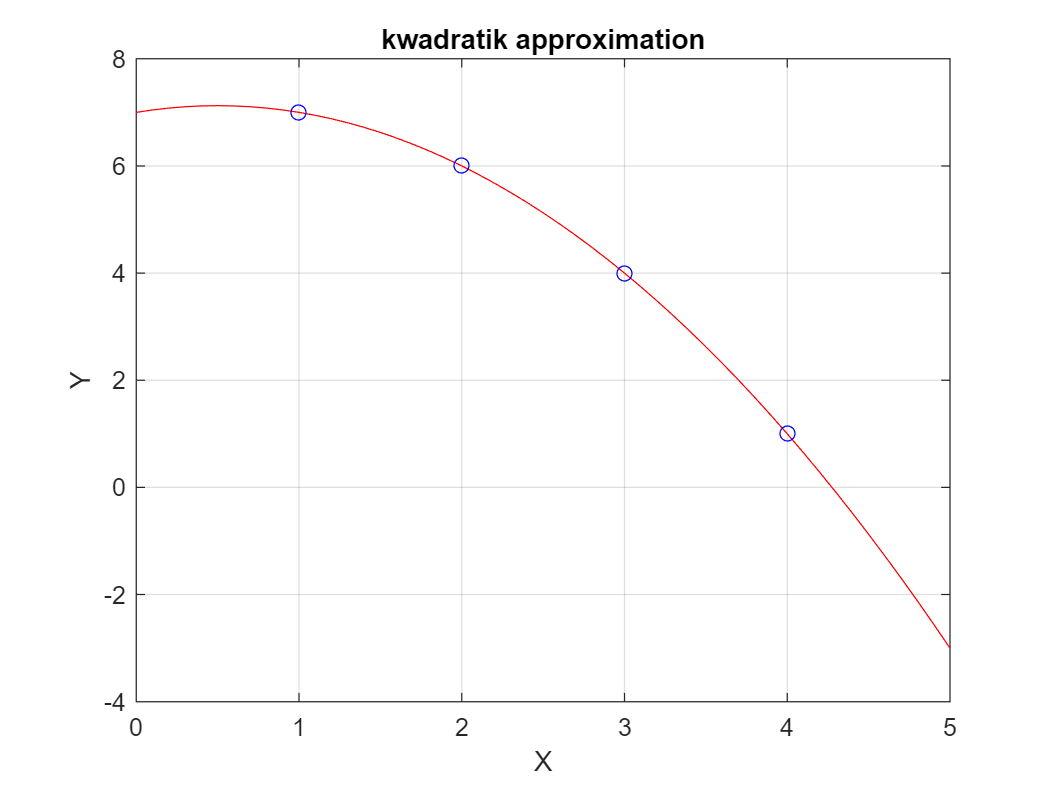

%plot the solution
x1=0:0.1:5;
y1=sol.a*(x1.^2)+sol.b*x1+sol.c;
figure(1)
plot(x1,y1,'r');
hold on;
plot(x,y,'bo');
hold off; grid on;
xlabel('X'), ylabel('Y'),
title('kwadratik approximation')